# 3. Smoothing

clc
clear

## 3.1 Smoothing of noisy data

office = office256;
add = gaussnoise(office, 16); %adds white (uncorrelated)Gaussian noise
sap = sapnoise(office, 0.1, 255); %adds salt-and-pepper noise 

figure(31)
subplot(2, 4, 1);
showgrey(office);
title('original');
subplot(2, 4, 2);
showgrey(add);
title('gaussnoise');
subplot(2, 4, 3);
showgrey(sap);
title('sapnoise');

subplot(2, 4, 5);
office_r_gaussftt = gaussfft(add, 10);
showgrey(office_r_gaussftt);
title('smooth with gaussfft');

subplot(2, 4, 6);
office_r_disgaussftt = discgaussfft(add, 10);

ans =    256   256


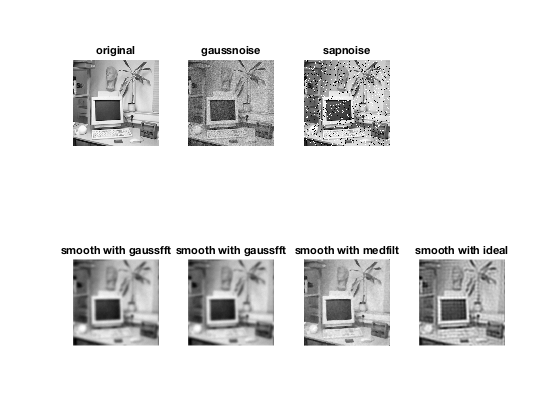

showgrey(office_r_disgaussftt);
title('smooth with gaussfft');

subplot(2, 4, 7);
office_r_medfilt = medfilt(add, 5);
showgrey(office_r_medfilt);
title('smooth with medfilt');

subplot(2, 4, 8);
office_r_ideal = ideal(add, 0.1);
showgrey(office_r_ideal);
title('smooth with ideal');

## 3.1 Smoothing of Gaussian noisy data - Gaussian, median and ideal low-pass filters

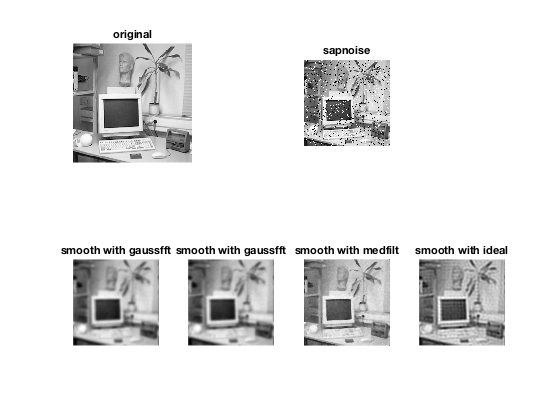

clc
clear

office = office256;
add = gaussnoise(office, 16); %adds white (uncorrelated)Gaussian noise
sap = sapnoise(office, 0.1, 255); %adds salt-and-pepper noise 

variance_t = [0.8, 1.5, 2.5];
win_size = [3, 4, 5];
cutoff_freq = [0.1, 0.18, 0.22];

% Gaussian filter
figure(31)
subplot(2, 3, 1);
showgrey(office);
title('original');

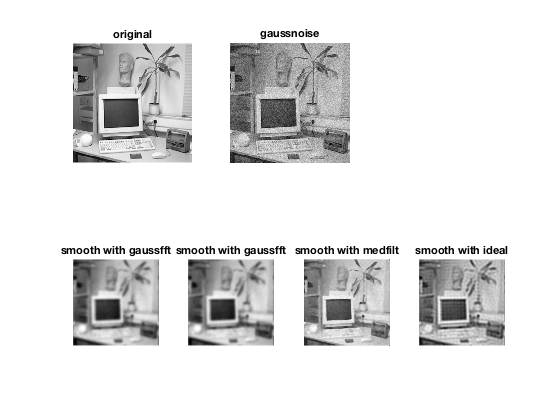

subplot(2, 3, 2);
showgrey(add);
title('gaussnoise');

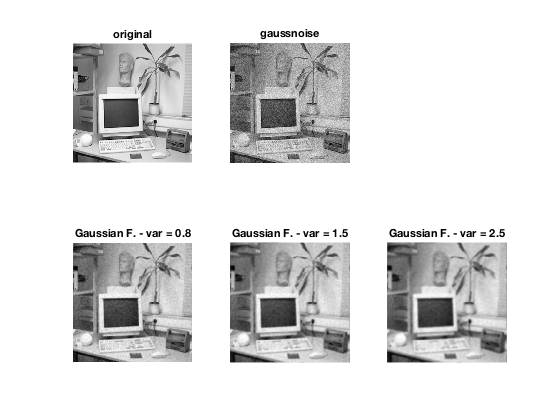

% subplot(2, 3, 3);
% showgrey(sap);
% title('sapnoise');

for i = 4:6
subplot(2, 3, i);
office_r_gaussftt = gaussfft(add, variance_t(i-3));
showgrey(office_r_gaussftt);
title(['Gaussian F. - var = ', num2str(variance_t(i-3))]);
end

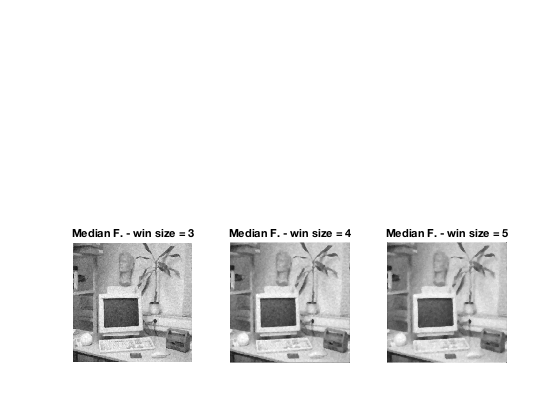


% Median filter
figure(32)
%subplot(2, 3, 1);
%showgrey(office);
%title('original');
%subplot(2, 3, 2);
%showgrey(add);
%title('gaussnoise');
% subplot(2, 3, 3);
% showgrey(sap);
% title('sapnoise');

for i = 4:6
subplot(2, 3, i);
office_r_medfilt = medfilt(add, win_size(i-3));
showgrey(office_r_medfilt);
title(['Median F. - win size = ', num2str(win_size(i-3))]);
end

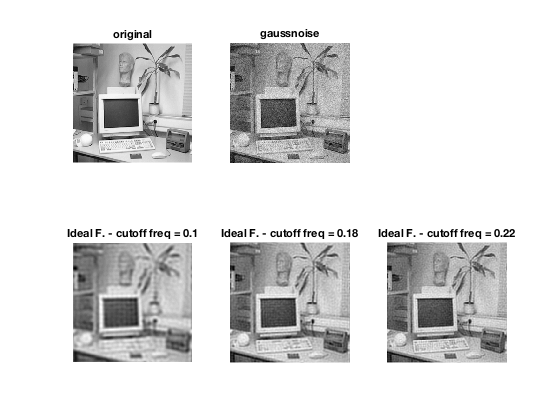


% Ideal low-pass filter
figure(33)
subplot(2, 3, 1);
showgrey(office);
title('original');
subplot(2, 3, 2);
showgrey(add);
title('gaussnoise');
% subplot(2, 3, 3);
% showgrey(sap);
% title('sapnoise');

for i = 4:6
subplot(2, 3, i);
office_r_ideal = ideal(add, cutoff_freq(i-3));
showgrey(office_r_ideal);
title(['Ideal F. - cutoff freq = ', num2str(cutoff_freq(i-3))]);
end

## 3.1 Smoothing of SAP noisy data - Gaussian, median and ideal low-pass filters

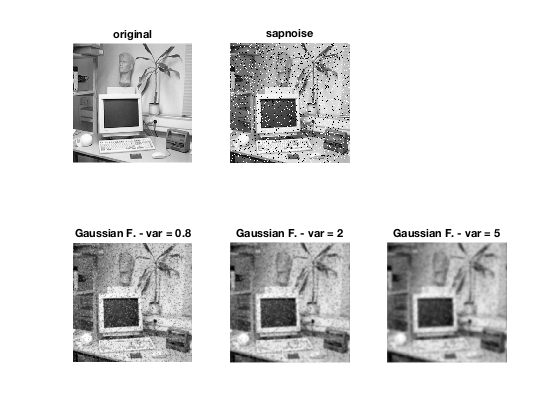

clc
clear

office = office256;
add = gaussnoise(office, 16); %adds white (uncorrelated)Gaussian noise
sap = sapnoise(office, 0.1, 255); %adds salt-and-peppar noise 

variance_t = [0.8, 2, 5];
win_size = [3, 4, 5];
cutoff_freq = [0.1, 0.13, 0.18];

% Gaussian filter
figure(34)
subplot(2, 3, 1);
showgrey(office);
title('original');
% subplot(2, 3, 2);
% showgrey(add);
% title('gaussnoise');
subplot(2, 3, 2);
showgrey(sap);
title('sapnoise');

for i = 4:6
subplot(2, 3, i);
office_r_gaussftt = gaussfft(sap, variance_t(i-3));
showgrey(office_r_gaussftt);
title(['Gaussian F. - var = ', num2str(variance_t(i-3))]);
end

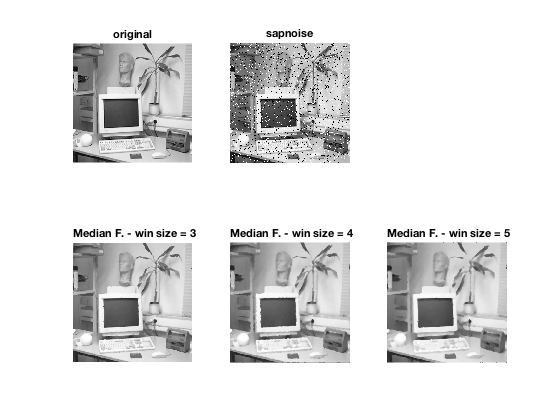


% Median filter
figure(35)
subplot(2, 3, 1);
showgrey(office);
title('original');
% subplot(2, 3, 2);
% showgrey(add);
% title('gaussnoise');
subplot(2, 3, 2);
showgrey(sap);
title('sapnoise');

for i = 4:6
subplot(2, 3, i);
office_r_medfilt = medfilt(sap, win_size(i-3));
showgrey(office_r_medfilt);
title([' Median F. - win size = ', num2str(win_size(i-3))]);
end

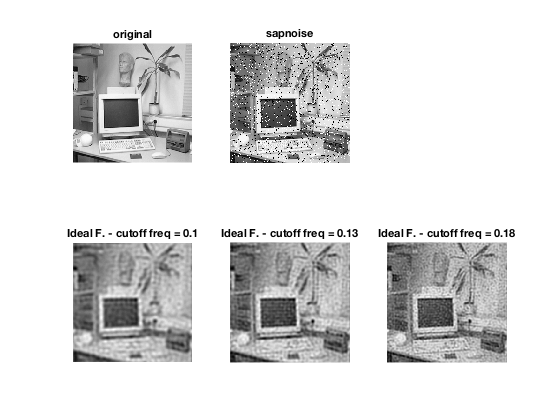


% Ideal low-pass filter
figure(36)
subplot(2, 3, 1);
showgrey(office);
title('original');
% subplot(2, 3, 2);
% showgrey(add);
% title('gaussnoise');
subplot(2, 3, 2);
showgrey(sap);
title('sapnoise');

for i = 4:6
subplot(2, 3, i);
office_r_ideal = ideal(sap, cutoff_freq(i-3));
showgrey(office_r_ideal);
title(['Ideal F. - cutoff freq = ', num2str(cutoff_freq(i-3))]);
end

## 3.1 Plot for Latex

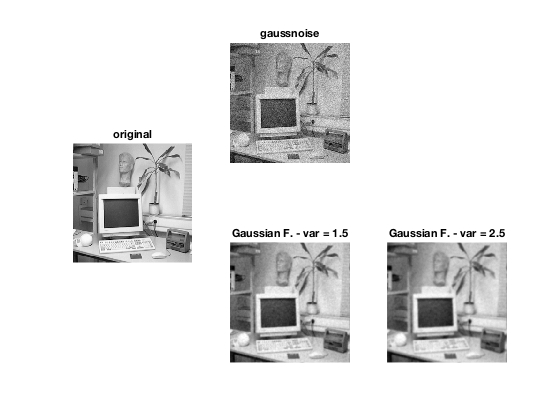

clc
clear

office = office256;
add = gaussnoise(office, 16); %adds white (uncorrelated)Gaussian noise
sap = sapnoise(office, 0.1, 255); %adds salt-and-peppar noise 

figure(31)
subplot(1, 3, 1);
showgrey(office);
title('original');

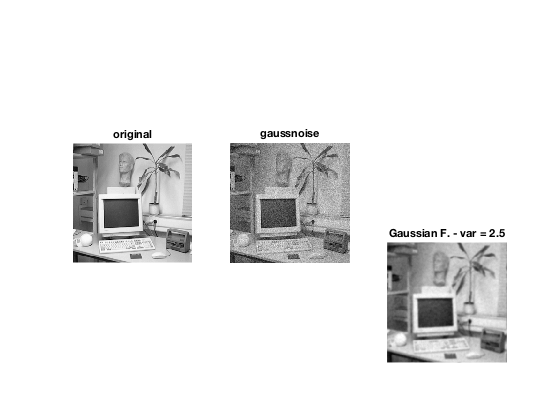

subplot(1, 3, 2);
showgrey(add);
title('gaussnoise');

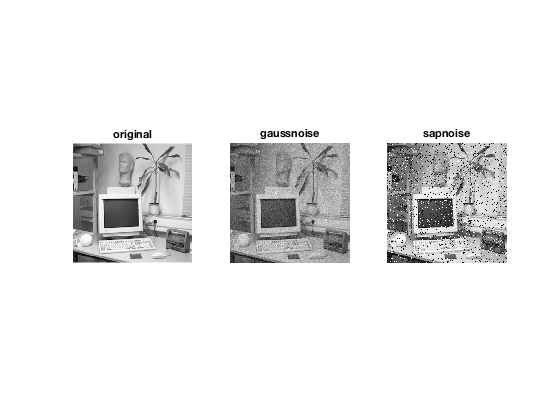

subplot(1, 3, 3);
showgrey(sap);
title('sapnoise');
saveas(gcf,'./plot/Lab1_3-1_Q17_fig1_original.png','png')

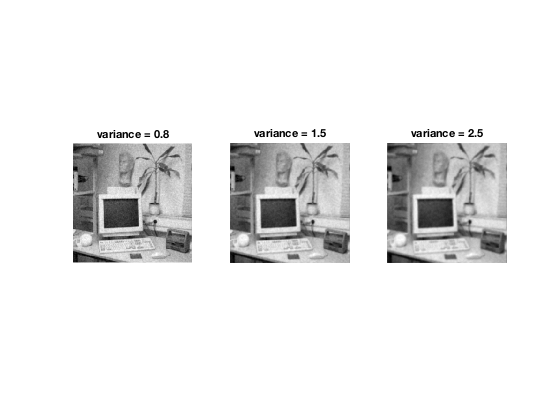


%Gaussian noise
variance_t = [0.8, 1.5, 2.5];
win_size = [3, 4, 5];
cutoff_freq = [0.1, 0.19, 0.22];

% Gaussian filter
figure(311)
for i = 1:3
subplot(1, 3, i);
office_r_gaussftt = gaussfft(add, variance_t(i));
showgrey(office_r_gaussftt);
title(['variance = ', num2str(variance_t(i))]);
end
saveas(gcf,'./plot/Lab1_3-1_Q17_fig2_GaussNoise_GaussF.png','png')

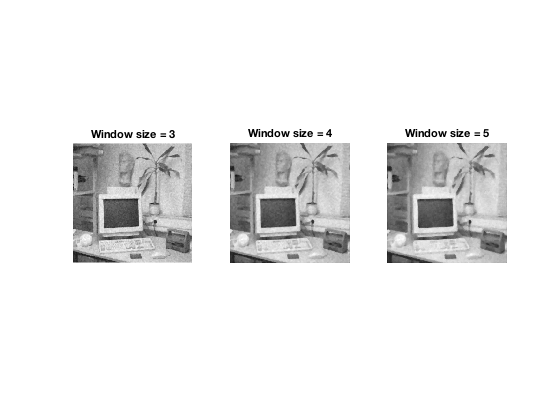


% Median filter
figure(312)
for i = 1:3
subplot(1, 3, i);
office_r_medfilt = medfilt(add, win_size(i));
showgrey(office_r_medfilt);
title(['Window size = ', num2str(win_size(i))]);
end
saveas(gcf,'./plot/Lab1_3-1_Q17_fig2_GaussNoise_MedianF.png','png')

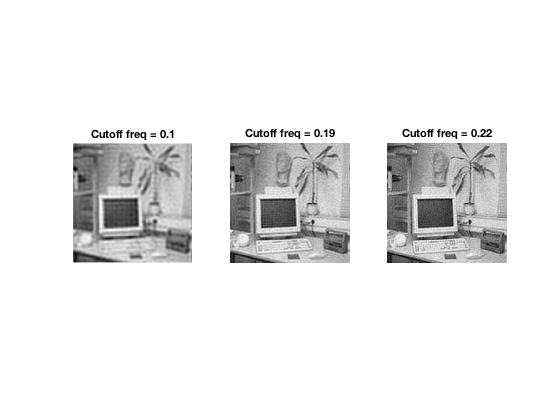


% Ideal low-pass filter
figure(313)
for i = 1:3
subplot(1, 3, i);
office_r_ideal = ideal(add, cutoff_freq(i));
showgrey(office_r_ideal);
title(['Cutoff freq = ', num2str(cutoff_freq(i))]);
end
saveas(gcf,'./plot/Lab1_3-1_Q17_fig2_GaussNoise_IdealF.png','png')

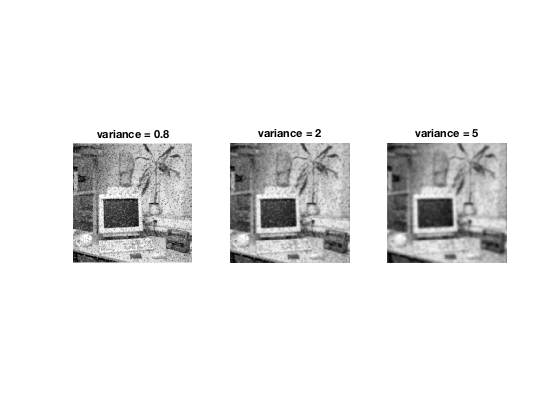


%SAP noise
variance_t = [0.8, 2, 5];
win_size = [3, 4, 5];
cutoff_freq = [0.1, 0.13, 0.18];

% Gaussian filter
figure(321)
for i = 1:3
subplot(1, 3, i);
office_r_gaussftt = gaussfft(sap, variance_t(i));
showgrey(office_r_gaussftt);
title(['variance = ', num2str(variance_t(i))]);
end
saveas(gcf,'./plot/Lab1_3-1_Q17_fig3_SAPNoise_GaussF.png','png')

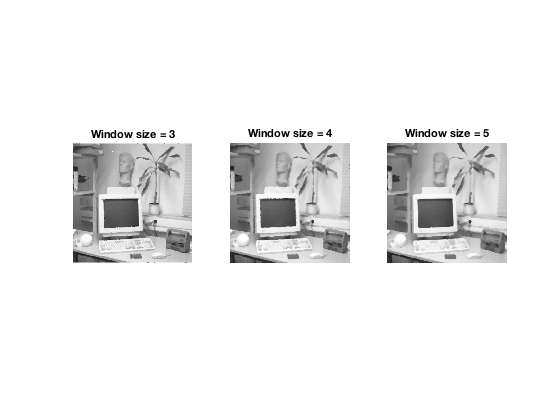


% Median filter
figure(322)
for i = 1:3
subplot(1, 3, i);
office_r_medfilt = medfilt(sap, win_size(i));
showgrey(office_r_medfilt);
title(['Window size = ', num2str(win_size(i))]);
end
saveas(gcf,'./plot/Lab1_3-1_Q17_fig3_SAPNoise_MedianF.png','png')

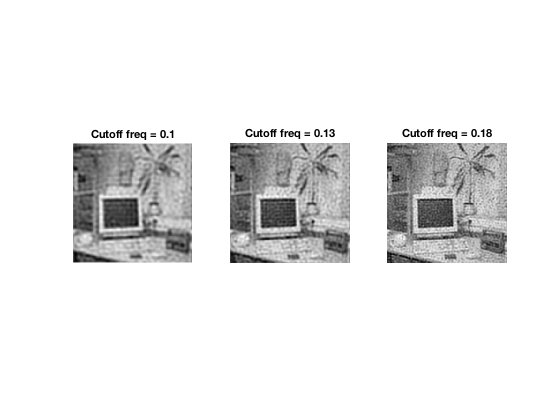


% Ideal low-pass filterfigure(312)
figure(323)
for i = 1:3
subplot(1, 3, i);
office_r_ideal = ideal(sap, cutoff_freq(i));
showgrey(office_r_ideal);
title(['Cutoff freq = ', num2str(cutoff_freq(i))]);
end
saveas(gcf,'./plot/Lab1_3-1_Q17_fig3_SAPNoise_IdealF.png','png')

## 3.2 Smoothing and subsampling

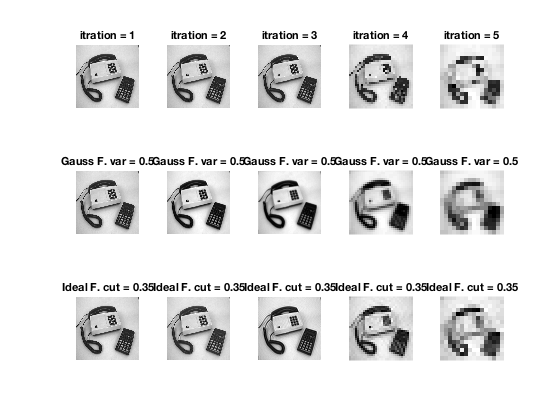

clc
clear

img = phonecalc256;
smoothimg = img;
smoothimg_i = img;
N=5;
for i=1:N
    if i>1 % generate subsampled versions
        img = rawsubsample(img);
        smoothimg = gaussfft(smoothimg, 0.5);
        smoothimg = rawsubsample(smoothimg);
        smoothimg_i = ideal(smoothimg_i, 0.35);
        smoothimg_i = rawsubsample(smoothimg_i);
    end
    subplot(3, N, i)
    showgrey(img)
    title(['itration = ',num2str(i)]);
    subplot(3, N, i+N)
    showgrey(smoothimg)
    title('Gauss F. var = 0.5');
    subplot(3, N, i+N*2)
    showgrey(smoothimg_i)
    title('Ideal F. cut = 0.35');
end

## 3.2 Smoothing and subsampling-find parameter for Gaussian filter

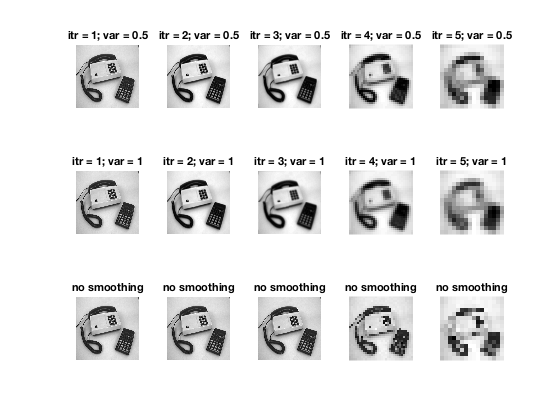

figure(322)
img = phonecalc256;
GaussVariance = [0.5, 1];
smoothimg = cell(1, length(GaussVariance));
for i = 1 :length(GaussVariance)
    smoothimg(i) = {img};
end
N=5;
for i=1:N
    for j = 1 : length(GaussVariance)
       if i>1 % generate subsampled versions
           if j == 1
            img = rawsubsample(img);
           end
        smoothimg(j) = {gaussfft(smoothimg{j}, GaussVariance(j))};
        smoothimg(j) = {rawsubsample(smoothimg{j})};
       end
        subplot(length(GaussVariance)+1, N, i + (j - 1) * N);
        showgrey(smoothimg{j})
        title(['itr = ',num2str(i),'; var = ',num2str(GaussVariance(j))]);
    end
    subplot(length(GaussVariance)+1, N, length(GaussVariance) * N + i);
    showgrey(img)
    title('no smoothing');
    
end

## 3.2 Smoothing and subsampling-find parameter for Ideal low pass filter

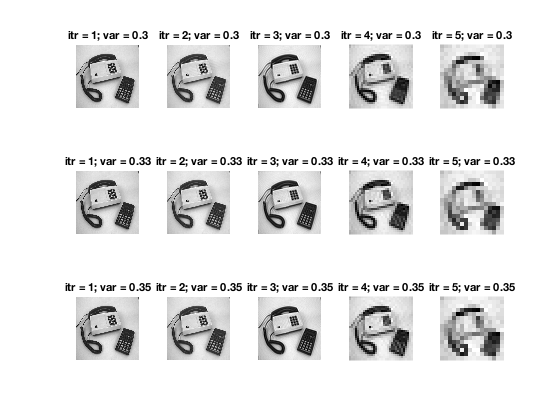

figure(323)
img = phonecalc256;
cut = [0.3, 0.33, 0.35];
smoothimg = cell(1, length(cut));
for i = 1 :length(cut)
    smoothimg(i) = {img};
end
N=5;
for i=1:N
    for j = 1 : length(cut)
       if i>1 % generate subsampled versions
        smoothimg(j) = {ideal(smoothimg{j}, cut(j))};
        smoothimg(j) = {rawsubsample(smoothimg{j})};
       end
        subplot(length(cut), N, i + (j - 1) * N);
        showgrey(smoothimg{j})
        title(['itr = ',num2str(i),'; var = ',num2str(cut(j))]);
    end
end